# **Talleres 13/14/15 – Modelo de un péndulo simple / Esteban Mejia Buitrago**

# **Objetivo**

Utilizar un método numérico para dar solución a la ecuación de estado no lineal de un péndulo simple. Además, intepretar los resultados al modificar diferentes parámetros a partir de la respuesta temporal y el diagrama de fase.

# **Enunciado**

Dada la siguiente la siguiente ecuación de estado de segundo orden no lineal de un modelo de un péndulo simple con fuerza tangencial, resolverla utilizando el método numérico de Runge-Kutta implementado en la función ode45 de MATLAB. 

                                    
$$x_1 =x_2$$


                                    
$$x_2 =-\frac{g}{l}\textrm{sen}\left(x_1 \right)-\frac{f}{m}x_2 +\frac{u}{m*l}$$


- Con los parámetros

                ~ $\theta$ = ángulo respecto a la vertical

                ~ $\omega$ = velocidad

                ~ *u* = fuerza externa

                ~ *l* = longitud del hilo

                ~ *m* = masa del cuerpo

                ~ *f* = coeficiente de fricción

                ~ *g* = gravedad

- Condicion inicial:

                ~ $\theta$ = 0

                ~ $\omega$ = 0

                ~ *u* = 1

                ~ *l* = 2

                ~ *m* = 1

                ~ *f* = 0.2

                ~ *g* = 9.8

**1.  Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones temporales con una entrada u = 1. ¿Para que valor máximo de la entrada el sistema rotará indefinidamente?**

- **Solución del sistema para u = 1 **

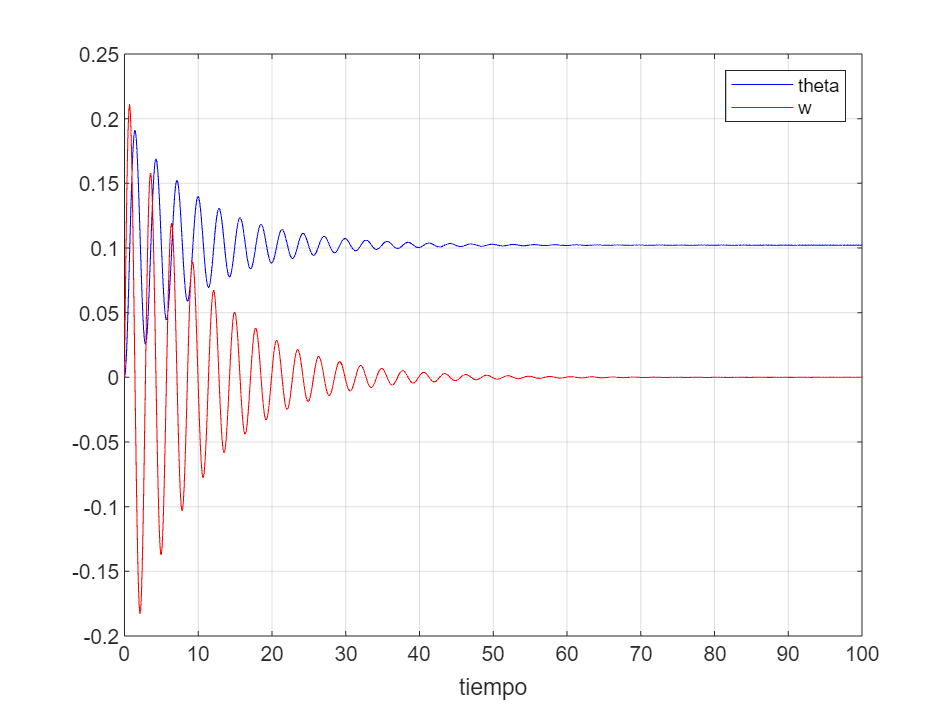

%solución del sistema con u=1
syms x1(t) x2(t)

m= 1; g=9.8; l=2; f=0.2; u=1;

f1 = x2;
f2 = (-g/l)*sin(x1)-(f/m)*x2+(u/(m*l));


f = odeFunction([f1 f2],[x1 x2]);%Parte derecha de la ecuación de estado de manera numérica
h = 0.1;
tmin = 0;
tmax = 100;
tspan = tmin:h:tmax;
ci = [0 0]; 
[t,x] = ode45(f,tspan,ci);
theta = x(:,1);
w = x(:,2);
plot(t,theta,'b',t,w,'r'),
xlabel('tiempo'),
legend('theta','w')

    Valor en el cual el sistema rota de forma indefinida

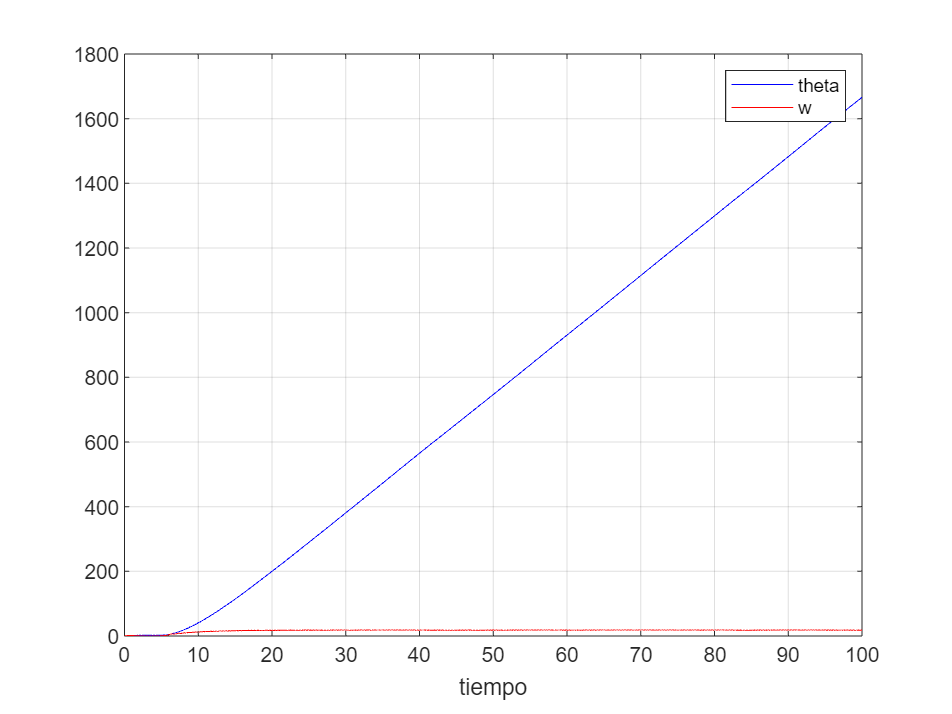

%solución del sistema con u=7.55 (valor donde el sistema rotará) indefinidamente
syms x1(t) x2(t)
m= 1; g=9.8; l=2; f=0.2; u=7.55;
f1 = x2;
f2 = (-g/l)*sin(x1)-(f/m)*x2+(u/(m*l));
f = odeFunction([f1 f2],[x1 x2]);
h = 0.1;
tmin = 0;
tmax = 100;
tspan = tmin:h:tmax;
ci = [0 0]; 
[t,x] = ode45(f,tspan,ci);
theta = x(:,1);
w = x(:,2);
plot(t,theta,'b',t,w,'r'),
xlabel('tiempo'),
legend('theta','w')

grid,

De la grafica podemos entender que la fuerza minima necesaria que para que rote indefinidamente el pendulo es de 7.55N

**2. **Trazar la curva de linealidad, es decir, el valor en el que se estabiliza el péndulo en función del valor de la entrada. El rango de entradas no debe superar el valor máximo calculado anteriormente.

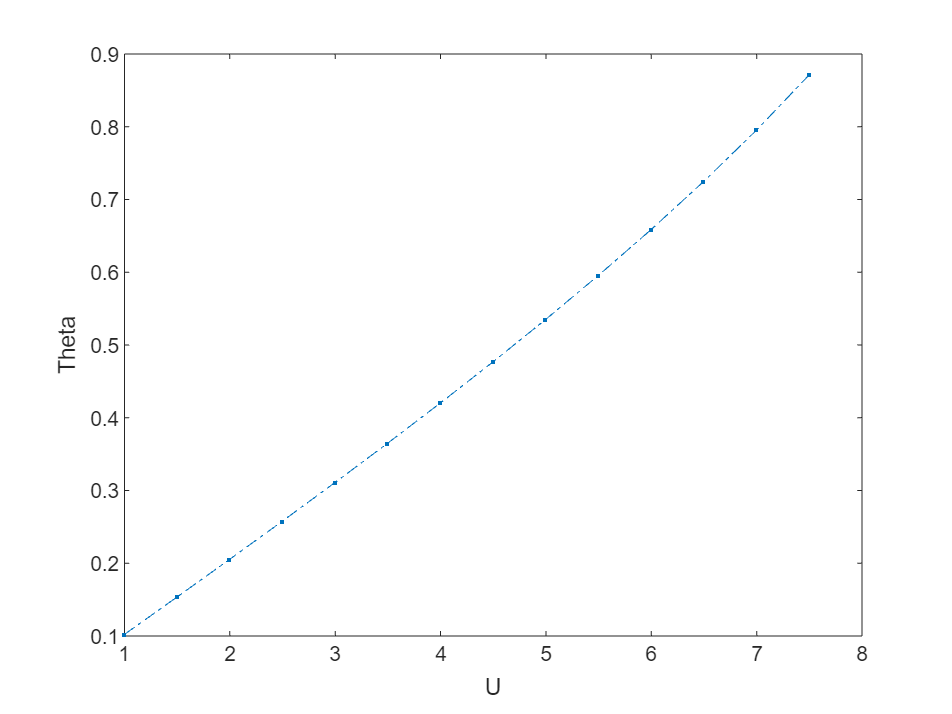

%Analizar el sistema al cambiar los valores de u
clc 
clear
syms x1(t) x2(t)
m= 1; g=9.8; l=2; f=0.2; 
u=1:0.5:7.55;
sol=[];
for i=1: numel(u)
    U=u(i);
    F1= x2;
    F2 = (-g/l)*sin(x1)-(f/m)*x2+(U/(m*l));
    F =odeFunction ([F1 F2], [x1 x2]);
    h=0.01;
    tspan=0:h:100;
    ci=[0 0];
    [~,sol{i}]= ode45(F, tspan, ci);
    theta(i) = sol{i}(end,1);
     
end
plot (u,theta, '.-.');
xlabel ('U');
ylabel ('Theta');

De la grafica se puede observar que con la fuerza que aplicada y el angulo que mantiene el pendulo tienen una relacion directa, ya que al aumentar el de la fuerza tambien aumenta el angulo

**3.** Dibujar el retrato de fase para un cambio en la condición inicial de la velocidad angular entre 3 y 6 rad/s con incrementos de 0.5 rad/s. Interpretar el resultado. ¿Para qué valor de la frecuencia angular inicial el péndulo da una vuelta? ¿Para qué valor da tres vueltas? Observar los puntos de equilibrio.

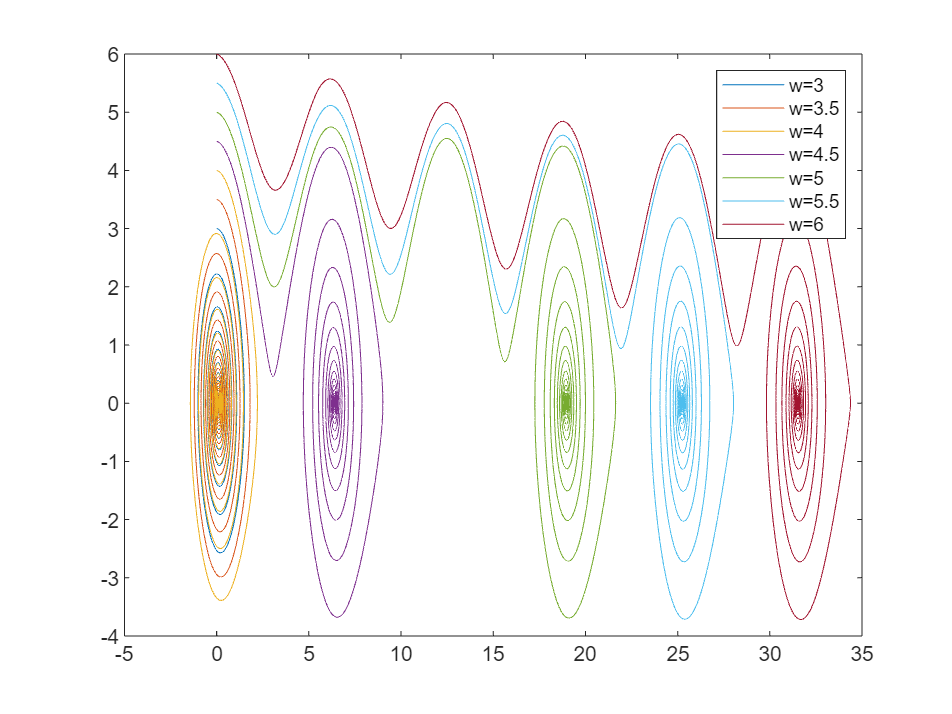

%Analizar el sistema al cambiar los valores de w
clc 
clear
m= 1; g=9.8; l=2; f=0.2; u=1;
w0=3:0.5:6;

for i=1: numel(w0)
    syms x1(t) x2(t)
    F1= x2;
    F2 = (-g/l)*sin(x1)-(f/m)*x2+(u/(m*l));
    F =odeFunction ([F1 F2], [x1 x2]);
    h=0.01;
    tspan=0:h:100;
    ci=[0 w0(i)];
    [~,sol]= ode45(F, tspan, ci);
    theta = sol(:,1);
    w = sol(:,2);
    plot (theta,w);
    hold on
     
end
hold off
legend ('w=3','w=3.5','w=4', 'w=4.5','w=5','w=5.5','w=6')

Acá se puede ver que con las condiciones iniciales de 4.5 y 5 el pendulo dara una y tres vueltas

`4. `Dibujar el retrato de fase para un cambio en la condición inicial de la posición angular entre -6 y 6 rad con incrementos de 0.5 rad. Interpretar el resultado. Observar los tres únicos puntos de equilibrio.

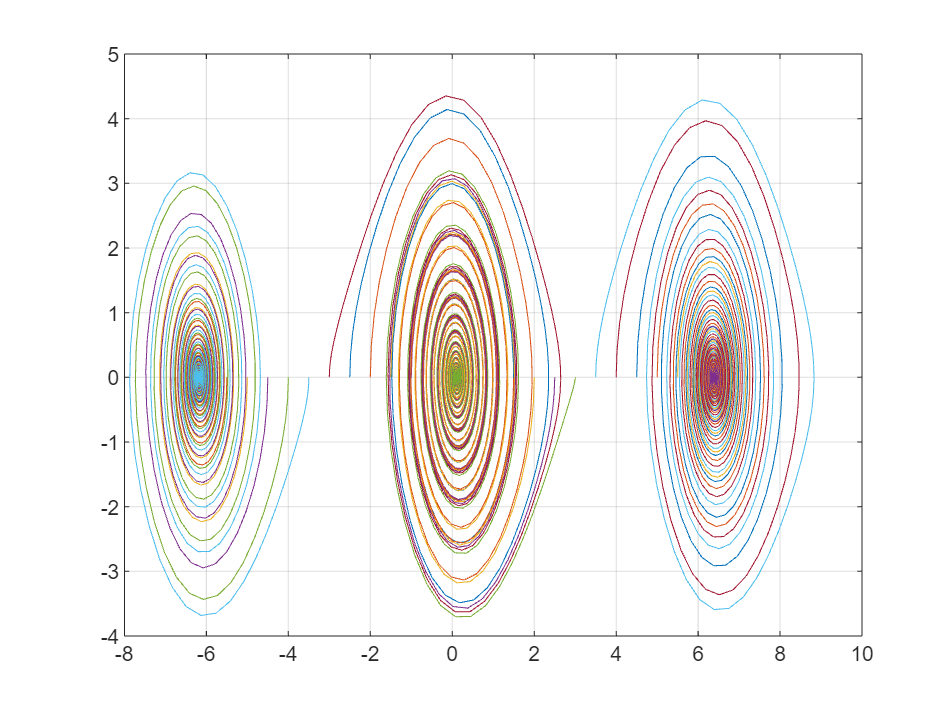

%Analizar el sistema al cambiar los valores de w
clc 
clear
m= 1; g=9.8; l=2; f=0.2; u=1;
teta0=-6:0.5:6;
for i=1: numel(teta0)
   syms x1(t) x2(t)
   F1= x2;
   F2 = (-g/l)*sin(x1)-(f/m)*x2+(u/(m*l));
   F =odeFunction ([F1 F2], [x1 x2]);
   h=0.1;
   tspan=0:h:500;
   ci=[teta0(i) 0];
   [~,sol]= ode45(F, tspan, ci);
   w = sol(:,1);
   teta = sol(:,2);
   plot (w,teta);
   hold on 
     
end
grid,
hold off

Acá vemos como con las condiciones iniciales entre -8 y-3.5 el punto de equilibrio es -6, con las condiciones iniciales entre -3 y 3 el punto de equilibrio es 0 y para las condiciones entre 3.5 y 9 el punto de equilibrio es de 6.3

**5.** Explicar el efecto del cambio de la longitud del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

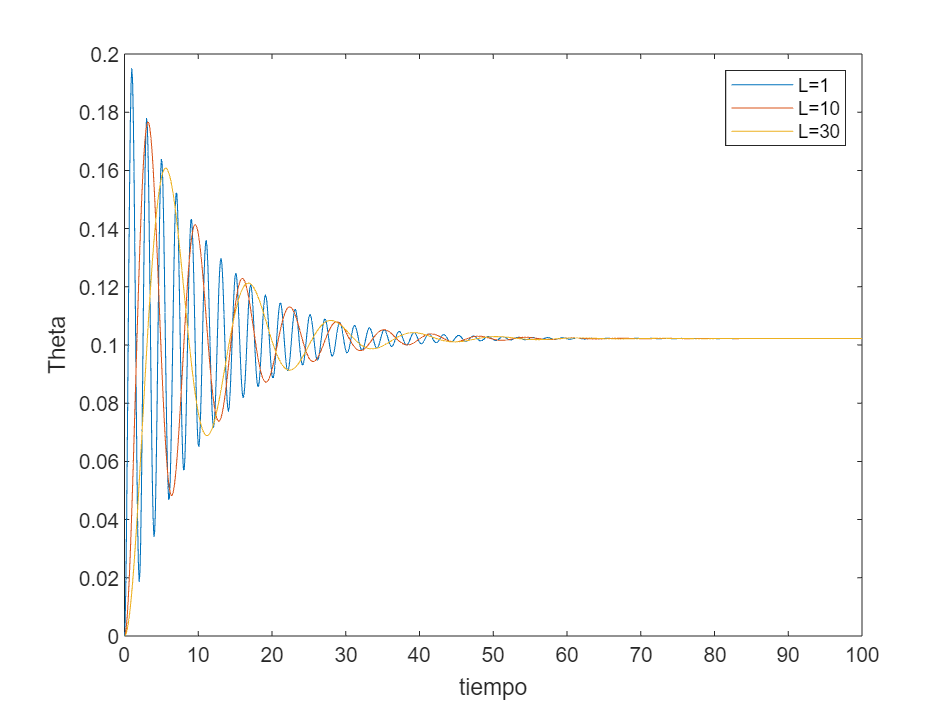

clc 
clear
syms x1(t) x2(t)
m= 1; g=9.8; u=1; f=0.2; 
l= [1 10 30];
sol=[];
for i=1: numel(l)
    L=l(i);
    F1= x2;
    F2 = (-g/L)*sin(x1)-(f/m)*x2+(u/(m*L));
    F =odeFunction ([F1 F2], [x1 x2]);
    h=0.1;
    tspan=0:h:100;
    ci=[0 0];
    [t1,sol]= ode45(F, tspan, ci);
    theta = sol(:,1);
    plot (t1,theta);
    xlabel ('tiempo');
    ylabel ('Theta');
    hold on
    
end
legend ('L=1','L=10','L=30')
hold off

Con la grafica vemos que independiente de la longitud de la cuerda el pendulo se estabilizara en la misma cantidad de tiempo sin importar que varie el numero de oscilaciones.

**6. **Explicar el efecto del cambio de la masa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

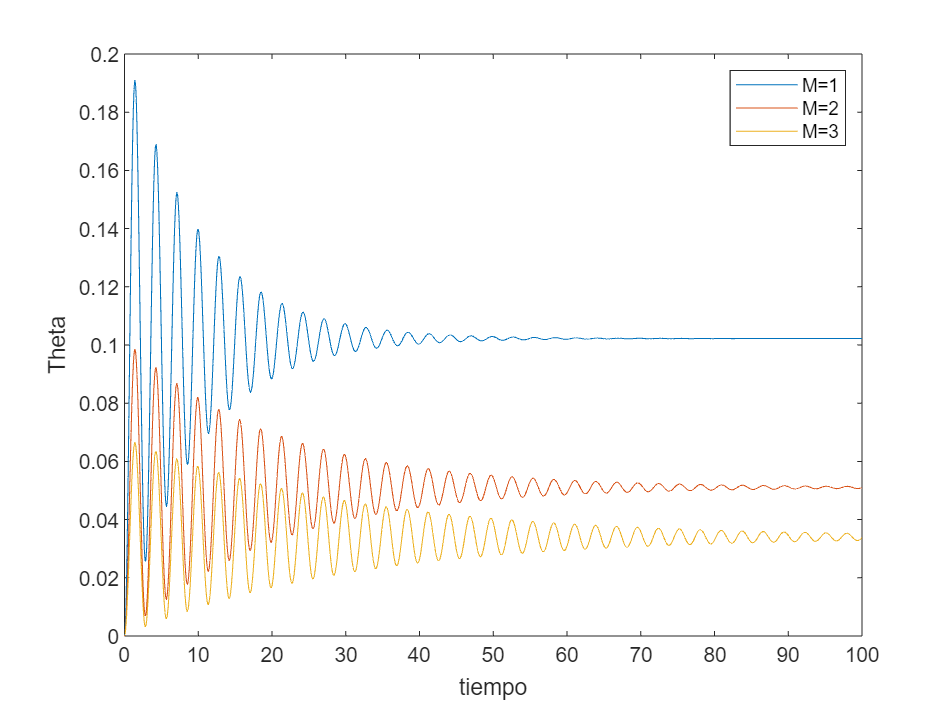

clc 
clear
syms x1(t) x2(t)
l= 2; g=9.8; u=1; f=0.2; 
m= [1 2 3 ];
sol=[];
for i=1: numel(m)
    M=m(i);
    F1= x2;
    F2 = (-g/l)*sin(x1)-(f/M)*x2+(u/(M*l));
    F =odeFunction ([F1 F2], [x1 x2]);
    h=0.1;
    tspan=0:h:100;
    ci=[0 0];
    [t1,sol]= ode45(F, tspan, ci);
    theta = sol(:,1);
    plot (t1,theta);
    xlabel ('tiempo');
    ylabel ('Theta');
    hold on
         
end

legend ('M=1','M=2','M=3')
hold off

Al aumentar la masa del pendulo este tiende a tardar más en estabilizarse.

**7. **Explicar el efecto del cambio de la fricción viscosa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

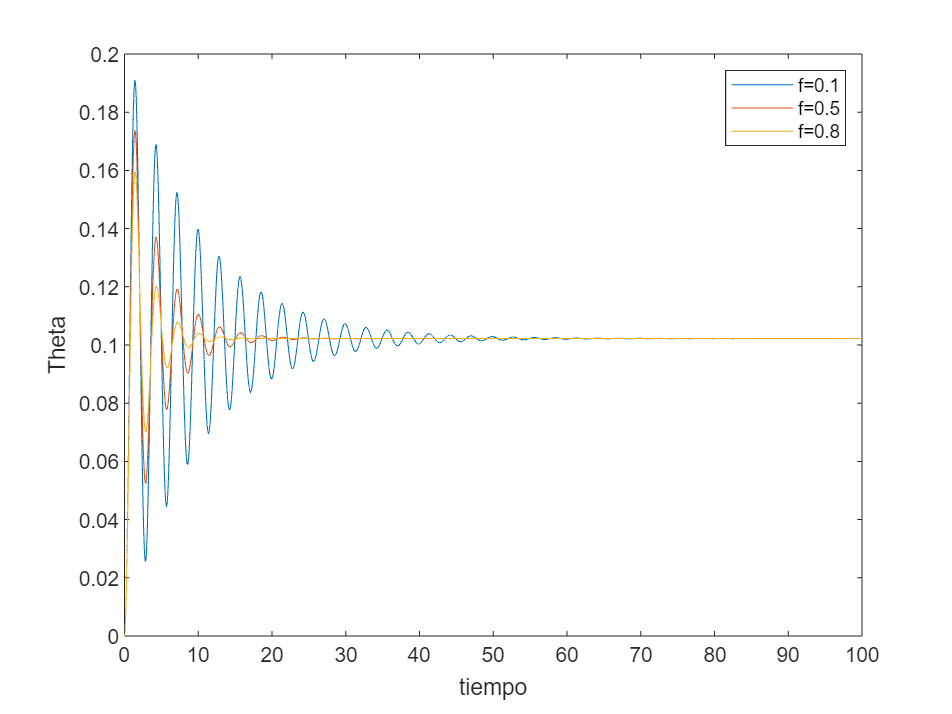

clc 
clear
syms x1(t) x2(t)
l= 2; g=9.8; u=1; m=1; 
f= [0.2 0.5 0.8];
sol=[];
for i=1: numel(f)
    F1= x2;
    F2 = (-g/l)*sin(x1)-(f(i)/m)*x2+(u/(m*l));
    F =odeFunction ([F1 F2], [x1 x2]);
    h=0.1;    
    tspan=0:h:100;
    ci=[0 0];
    [t1,sol]= ode45(F, tspan, ci);
    theta = sol(:,1);
    plot (t1,theta);
    xlabel ('tiempo');
    ylabel ('Theta');
    hold on     
end

legend ('f=0.1','f=0.5','f=0.8')
hold off

Acá vemos como el numero de oscilaciones se relaciona con la fricción viscosa, pues al aumentar su valor las oscilaciones en el pendulo van disminuyendo

**8. **Si f = 0, u = 0 (movimiento libre no amortiguado) y la posición angular inicial ω(0) es menor a unos 30° (0.5 radianes, aproximadamente), se puede aproximar el seno del ángulo en radianes por el ángulo (comprobar con la calculadora o MATLAB) y el modelo es lineal. Obtener la ecuación de estado, pasar a la ecuación diferencial homogénea con coeficientes constantes y resolverla analíticamente. ¿Cómo se puede medir la aceleración de la gravedad si se conoce la longitud? ¿Cómo se puede obtener la longitud si se conoce la aceleración de la gravedad? Comprobar los resultados con MATLAB

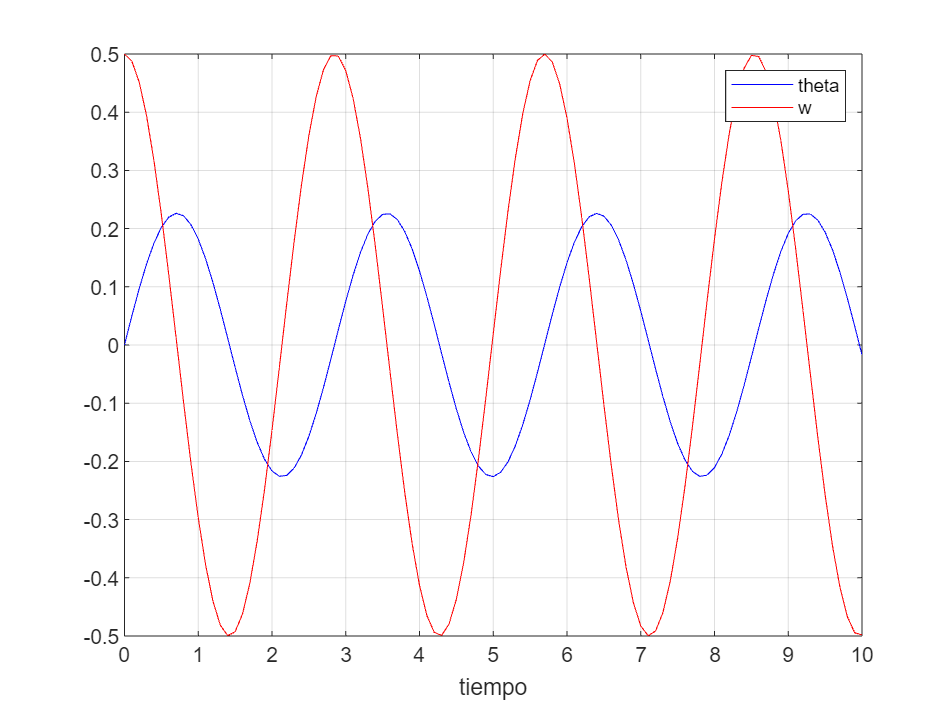

syms x1(t) x2(t)

m= 1; g=9.8; l=2; f=0; u=0;

f1 = x2;
f2 = (-g/l)*sin(x1)-(f/m)*x2+(u/(m*l));


f = odeFunction([f1 f2],[x1 x2]);

h = 0.1;

tmin = 0;
tmax = 10;
tspan = tmin:h:tmax;

ci = [0 0.5]; 
[t,x] = ode45(f,tspan,ci);

theta = x(:,1);
w = x(:,2);

plot(t,theta,'b',t,w,'r'),

xlabel('tiempo'),
legend('theta','w')

grid,

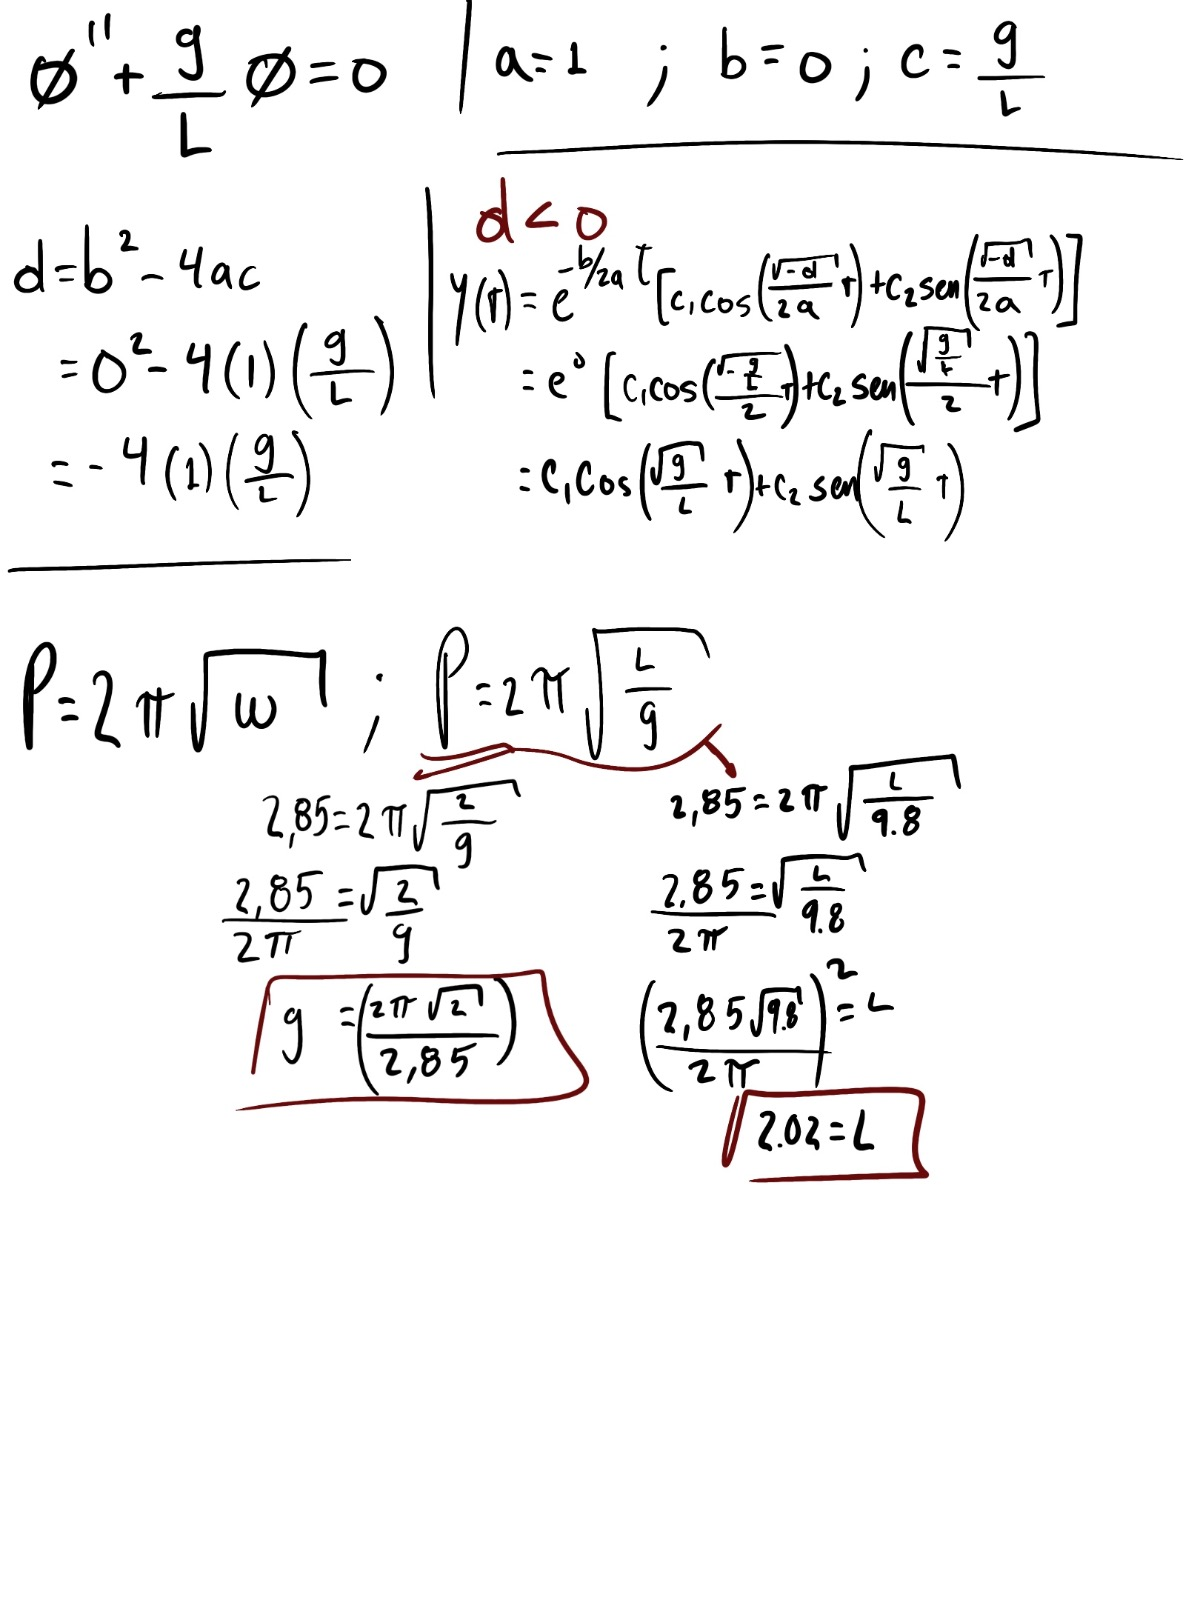

**9. **Si se conoce la respuesta temporal de un péndulo con fuerza igual a 1 N, *l* = 2 y *g* = 9.8, hallar aproximadamente por tanteo los valores de *f* y *m*. Explicar el procedimiento. Tener en cuenta los resultados de las tareas 6 y 7.

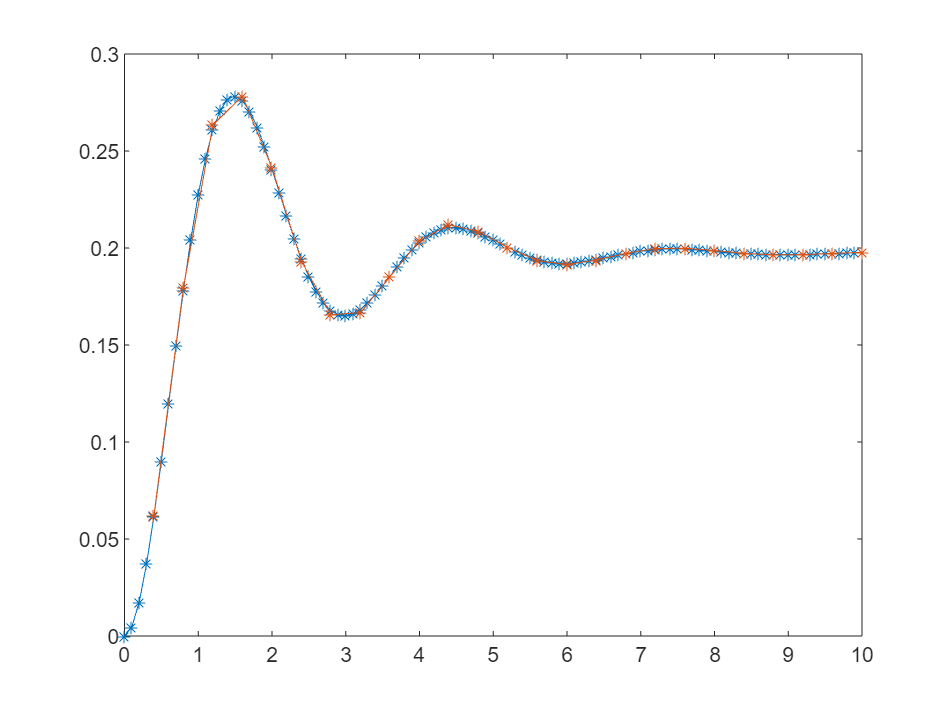

clear;
t1 = [0.4 0.8 1.2 1.6 2 2.4 2.8 3.2 3.6 4 4.4 4.8 5.2 5.6 6 6.4 6.8 7.2 7.6 8 8.4 8.8 9.2 9.6 10];
ang= [0.0621 0.1797 0.2635 0.2783 0.2414 0.1932 0.1656 0.1667 0.1852 0.2038 0.2119 0.2086 0.2002 0.1934 0.1915 0.1938 0.1973 0.1997 0.1999 0.1987 0.1972 0.1965 0.1966 0.1972 0.1978];
m= 0.52; 
f= 0.63; 
g= 9.8; 
l= 2; 
u = 1; 

     syms x1(t) x2(t)  
     f1 = x2;  
     f2 = -((g/l)*sin(x1))-((f/m)*x2)+(u/(m*l));
     F = odeFunction([f1 f2],[x1 x2]);  
     h = 0.1; 
     tmin = 0;
     tmax = 10;
     tspan = tmin:h:tmax; 
     ci = [0 0]; 
     [t,sol] = ode45(F,tspan,ci); 
     teta = sol(:,1); 
   
plot(t,teta,'*-')
hold on
plot(t1,ang,'*-')
hold off

Los valores de la masa y fricción viscosa con los cuales el pendulo se comportara como en el modelo son de 0.52 y 0.63.